clc;
clear;
close all;

% Draw a square in y-z plane
YZ1 = [0, 0.2, 0.1, -0.523]

YZ1 =          0    0.2000    0.1000   -0.5230


YZ2 = [0, 0.2, 0.2, -0.523]

YZ2 =          0    0.2000    0.2000   -0.5230


YZ3 = [0, 0.1, 0.2, -0.523]

YZ3 =          0    0.1000    0.2000   -0.5230


YZ4 = [0, 0.1, 0.1, -0.523]

YZ4 =          0    0.1000    0.1000   -0.5230



T1 = getFirstValidIKSol( OpenManipIK(YZ1(1),YZ1(2),YZ1(3),YZ1(4)) )

T1 = struct with fields:
    joint1_angle: 0
    joint2_angle: -0.3869
    joint3_angle: 0.7276
    joint4_angle: 0.1823


T2 = getFirstValidIKSol( OpenManipIK(YZ2(1),YZ2(2),YZ2(3),YZ2(4)) )

T2 = struct with fields:
    joint1_angle: 0
    joint2_angle: -0.3328
    joint3_angle: -0.1480
    joint4_angle: 1.0038


T3 = getFirstValidIKSol( OpenManipIK(YZ3(1),YZ3(2),YZ3(3),YZ3(4)) )

T3 = struct with fields:
    joint1_angle: 0
    joint2_angle: -0.9611
    joint3_angle: 0.1115
    joint4_angle: 1.3726


T4 = getFirstValidIKSol( OpenManipIK(YZ4(1),YZ4(2),YZ4(3),YZ4(4)) )

T4 = struct with fields:
    joint1_angle: 0
    joint2_angle: -1.4505
    joint3_angle: 1.0633
    joint4_angle: 0.9102



theta1 = [T1.joint1_angle,T2.joint1_angle,T3.joint1_angle,T4.joint1_angle]

theta1 =      0     0     0     0


theta2 = [T1.joint2_angle,T2.joint2_angle,T3.joint2_angle,T4.joint2_angle]

theta2 =    -0.3869   -0.3328   -0.9611   -1.4505


theta3 = [T1.joint3_angle,T2.joint3_angle,T3.joint3_angle,T4.joint3_angle]

theta3 =     0.7276   -0.1480    0.1115    1.0633


theta4 = [T1.joint4_angle,T2.joint4_angle,T3.joint4_angle,T4.joint4_angle]

theta4 =     0.1823    1.0038    1.3726    0.9102



for i = 1:length(theta1)
    [X,Y,Z] = getCoordinate(theta1(i),theta2(i),theta3(i),theta4(i))
    plot3([0,X(1)],[0,Y(1)],[0,Z(1)],'Color','black','LineWidth',2,'Marker','_')
    hold on
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    title("Forward Kinematics")
    grid on
    plot3([X(1),X(2)],[Y(1),Y(2)],[Z(1),Z(2)],'Color','b','LineWidth',2,'Marker','_')
    plot3([X(2),X(3)],[Y(2),Y(3)],[Z(2),Z(3)],'Color','g','LineWidth',2,'Marker','|')
    plot3([X(3),X(4)],[Y(3),Y(4)],[Z(3),Z(4)],'Color','r','LineWidth',2,'Marker','o')
end

joint1_angle = 0

joint2_angle = -0.3869

joint3_angle = 0.7276

joint4_angle = 0.1823

x1 = 0

y1 = 0

z1 = 0.0770

A =          0         0    0.0770


x2 = -9.3929e-18

y2 = -0.0260

z2 = 0.2044

B =    -0.0000   -0.0260    0.2044


x3 = 3.0056e-19

y3 = 0.0908

z3 = 0.1629

C =     0.0000    0.0908    0.1629


x4 = 1.0838e-17

y4 = 0.2000

z4 = 0.1000

D =     0.0000    0.2000    0.1000


X = 	1.0e+-16 *

         0   -0.0939    0.0030    0.1084


Y =          0   -0.0260    0.0908    0.2000


Z =     0.0770    0.2044    0.1629    0.1000


X = 	1.0e+-16 *

         0   -0.0939    0.0030    0.1084


Y =          0   -0.0260    0.0908    0.2000


Z =     0.0770    0.2044    0.1629    0.1000


joint1_angle = 0

joint2_angle = -0.3328

joint3_angle = -0.1480

joint4_angle = 1.0038

x1 = 0

y1 = 0

z1 = 0.0770

A =          0         0    0.0770


x2 = -9.0434e-18

y2 = -0.0191

z2 = 0.2056

B =    -0.0000   -0.0191    0.2056


x3 = -5.8227e-18

y3 = 0.0908

z3 = 0.2629

C =    -0.0000    0.0908    0.2629


x4 = 4.7149e-18

y4 = 0.2000

z4 = 0.2000

D =     0.0000    0.2000    0.2000


X = 	1.0e+-17 *

         0   -0.9043   -0.5823    0.4715


Y =          0   -0.0191    0.0908    0.2000


Z =     0.0770    0.2056    0.2629    0.2000


X = 	1.0e+-17 *

         0   -0.9043   -0.5823    0.4715


Y =          0   -0.0191    0.0908    0.2000


Z =     0.0770    0.2056    0.2629    0.2000


joint1_angle = 0

joint2_angle = -0.9611

joint3_angle = 0.1115

joint4_angle = 1.3726

x1 = 0

y1 = 0

z1 = 0.0770

A =          0         0    0.0770


x2 = -1.1257e-17

y2 = -0.0910

z2 = 0.1698

B =    -0.0000   -0.0910    0.1698


x3 = -1.1946e-17

y3 = -0.0092

z3 = 0.2629

C =    -0.0000   -0.0092    0.2629


x4 = -1.4083e-18

y4 = 0.1000

z4 = 0.2000

D =    -0.0000    0.1000    0.2000


X = 	1.0e+-16 *

         0   -0.1126   -0.1195   -0.0141


Y =          0   -0.0910   -0.0092    0.1000


Z =     0.0770    0.1698    0.2629    0.2000


X = 	1.0e+-16 *

         0   -0.1126   -0.1195   -0.0141


Y =          0   -0.0910   -0.0092    0.1000


Z =     0.0770    0.1698    0.2629    0.2000


joint1_angle = 0

joint2_angle = -1.4505

joint3_angle = 1.0633

joint4_angle = 0.9102

x1 = 0

y1 = 0

z1 = 0.0770

A =          0         0    0.0770


x2 = -9.9863e-18

y2 = -0.1240

z2 = 0.1161

B =    -0.0000   -0.1240    0.1161


x3 = -5.8227e-18

y3 = -0.0092

z3 = 0.1629

C =    -0.0000   -0.0092    0.1629


x4 = 4.7149e-18

y4 = 0.1000

z4 = 0.1000

D =     0.0000    0.1000    0.1000


X = 	1.0e+-17 *

         0   -0.9986   -0.5823    0.4715


Y =          0   -0.1240   -0.0092    0.1000


Z =     0.0770    0.1161    0.1629    0.1000


X = 	1.0e+-17 *

         0   -0.9986   -0.5823    0.4715


Y =          0   -0.1240   -0.0092    0.1000


Z =     0.0770    0.1161    0.1629    0.1000


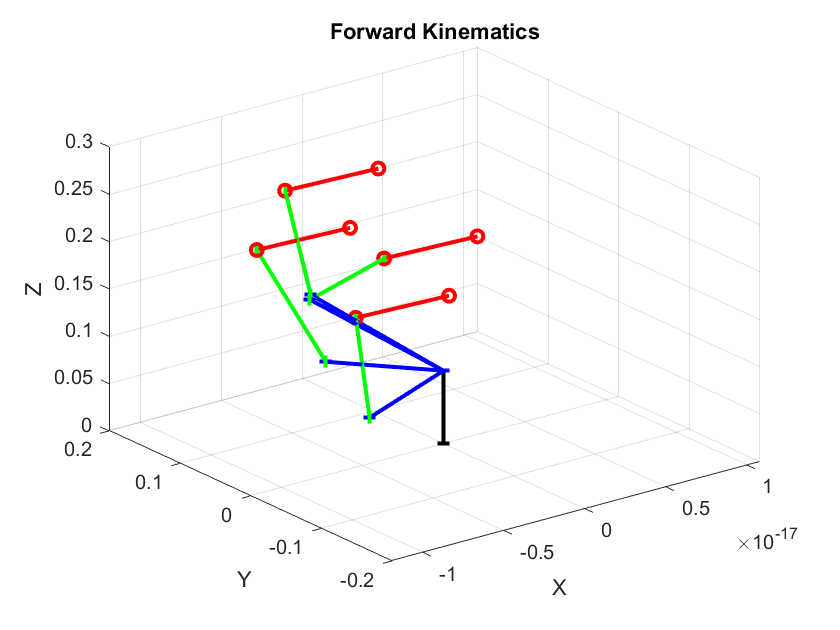

hold off


% Draw a square in x-y plane
XY1 = [0.05, 0.2, 0.2, -0.523]

XY1 =     0.0500    0.2000    0.2000   -0.5230


XY2 = [-0.05, 0.2, 0.2, -0.523]

XY2 =    -0.0500    0.2000    0.2000   -0.5230


XY3 = [-0.05, 0.1, 0.2, -0.523]

XY3 = 1×4
   -0.0500    0.1000    0.2000   -0.5230


XY4 = [0.05, 0.1, 0.2, -0.523]

XY4 = 1×4
    0.0500    0.1000    0.2000   -0.5230



T1 = getFirstValidIKSol( OpenManipIK(XY1(1),XY1(2),XY1(3),XY1(4)) )

T1 = struct with fields:
    joint1_angle: -0.2450
    joint2_angle: -0.2880
    joint3_angle: -0.1862
    joint4_angle: 0.9972


T2 = getFirstValidIKSol( OpenManipIK(XY2(1),XY2(2),XY2(3),XY2(4)) )

T2 = struct with fields:
    joint1_angle: 0.2450
    joint2_angle: -0.2880
    joint3_angle: -0.1862
    joint4_angle: 0.9972


T3 = getFirstValidIKSol( OpenManipIK(XY3(1),XY3(2),XY3(3),XY3(4)) )

T3 = struct with fields:
    joint1_angle: 0.4636
    joint2_angle: -0.8988
    joint3_angle: 0.1139
    joint4_angle: 1.3079


T4 = getFirstValidIKSol( OpenManipIK(XY4(1),XY4(2),XY4(3),XY4(4)) )

T4 = struct with fields:
    joint1_angle: -0.4636
    joint2_angle: -0.8988
    joint3_angle: 0.1139
    joint4_angle: 1.3079



theta1 = [T1.joint1_angle,T2.joint1_angle,T3.joint1_angle,T4.joint1_angle]

theta1 = 1×4
   -0.2450    0.2450    0.4636   -0.4636


theta2 = [T1.joint2_angle,T2.joint2_angle,T3.joint2_angle,T4.joint2_angle]

theta2 = 1×4
   -0.2880   -0.2880   -0.8988   -0.8988


theta3 = [T1.joint3_angle,T2.joint3_angle,T3.joint3_angle,T4.joint3_angle]

theta3 = 1×4
   -0.1862   -0.1862    0.1139    0.1139


theta4 = [T1.joint4_angle,T2.joint4_angle,T3.joint4_angle,T4.joint4_angle]

theta4 = 1×4
    0.9972    0.9972    1.3079    1.3079



for i = 1:length(theta1)
    [X,Y,Z] = getCoordinate(theta1(i),theta2(i),theta3(i),theta4(i))
    plot3([0,X(1)],[0,Y(1)],[0,Z(1)],'Color','black','LineWidth',2,'Marker','_')
    hold on
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    title("Forward Kinematics")
    grid on
    plot3([X(1),X(2)],[Y(1),Y(2)],[Z(1),Z(2)],'Color','b','LineWidth',2,'Marker','_')
    plot3([X(2),X(3)],[Y(2),Y(3)],[Z(2),Z(3)],'Color','g','LineWidth',2,'Marker','|')
    plot3([X(3),X(4)],[Y(3),Y(4)],[Z(3),Z(4)],'Color','r','LineWidth',2,'Marker','o')

end

joint1_angle = -0.2450

joint2_angle = -0.2880

joint3_angle = -0.1862

joint4_angle = 0.9972

x1 = 0

y1 = 0

z1 = 0.0770

A = 1×3
         0         0    0.0770


x2 = -0.0032

y2 = -0.0129

z2 = 0.2063

B = 1×3
   -0.0032   -0.0129    0.2063


x3 = 0.0235

y3 = 0.0941

z3 = 0.2629

C = 1×3
    0.0235    0.0941    0.2629


x4 = 0.0500

y4 = 0.2000

z4 = 0.2000

D = 1×3
    0.0500    0.2000    0.2000


X = 1×4
         0   -0.0032    0.0235    0.0500


Y = 1×4
         0   -0.0129    0.0941    0.2000


Z = 1×4
    0.0770    0.2063    0.2629    0.2000


X = 1×4
         0   -0.0032    0.0235    0.0500


Y = 1×4
         0   -0.0129    0.0941    0.2000


Z = 1×4
    0.0770    0.2063    0.2629    0.2000


joint1_angle = 0.2450

joint2_angle = -0.2880

joint3_angle = -0.1862

joint4_angle = 0.9972

x1 = 0

y1 = 0

z1 = 0.0770

A = 1×3
         0         0    0.0770


x2 = 0.0032

y2 = -0.0129

z2 = 0.2063

B = 1×3
    0.0032   -0.0129    0.2063


x3 = -0.0235

y3 = 0.0941

z3 = 0.2629

C = 1×3
   -0.0235    0.0941    0.2629


x4 = -0.0500

y4 = 0.2000

z4 = 0.2000

D = 1×3
   -0.0500    0.2000    0.2000


X = 1×4
         0    0.0032   -0.0235   -0.0500


Y = 1×4
         0   -0.0129    0.0941    0.2000


Z = 1×4
    0.0770    0.2063    0.2629    0.2000


X = 1×4
         0    0.0032   -0.0235   -0.0500


Y = 1×4
         0   -0.0129    0.0941    0.2000


Z = 1×4
    0.0770    0.2063    0.2629    0.2000


joint1_angle = 0.4636

joint2_angle = -0.8988

joint3_angle = 0.1139

joint4_angle = 1.3079

x1 = 0

y1 = 0

z1 = 0.0770

A = 1×3
         0         0    0.0770


x2 = 0.0380

y2 = -0.0761

z2 = 0.1753

B = 1×3
    0.0380   -0.0761    0.1753


x3 = -0.0012

y3 = 0.0024

z3 = 0.2629

C = 1×3
   -0.0012    0.0024    0.2629


x4 = -0.0500

y4 = 0.1000

z4 = 0.2000

D = 1×3
   -0.0500    0.1000    0.2000


X = 1×4
         0    0.0380   -0.0012   -0.0500


Y = 1×4
         0   -0.0761    0.0024    0.1000


Z = 1×4
    0.0770    0.1753    0.2629    0.2000


X = 1×4
         0    0.0380   -0.0012   -0.0500


Y = 1×4
         0   -0.0761    0.0024    0.1000


Z = 1×4
    0.0770    0.1753    0.2629    0.2000


joint1_angle = -0.4636

joint2_angle = -0.8988

joint3_angle = 0.1139

joint4_angle = 1.3079

x1 = 0

y1 = 0

z1 = 0.0770

A = 1×3
         0         0    0.0770


x2 = -0.0380

y2 = -0.0761

z2 = 0.1753

B = 1×3
   -0.0380   -0.0761    0.1753


x3 = 0.0012

y3 = 0.0024

z3 = 0.2629

C = 1×3
    0.0012    0.0024    0.2629


x4 = 0.0500

y4 = 0.1000

z4 = 0.2000

D = 1×3
    0.0500    0.1000    0.2000


X = 1×4
         0   -0.0380    0.0012    0.0500


Y = 1×4
         0   -0.0761    0.0024    0.1000


Z = 1×4
    0.0770    0.1753    0.2629    0.2000


X = 1×4
         0   -0.0380    0.0012    0.0500


Y = 1×4
         0   -0.0761    0.0024    0.1000


Z = 1×4
    0.0770    0.1753    0.2629    0.2000


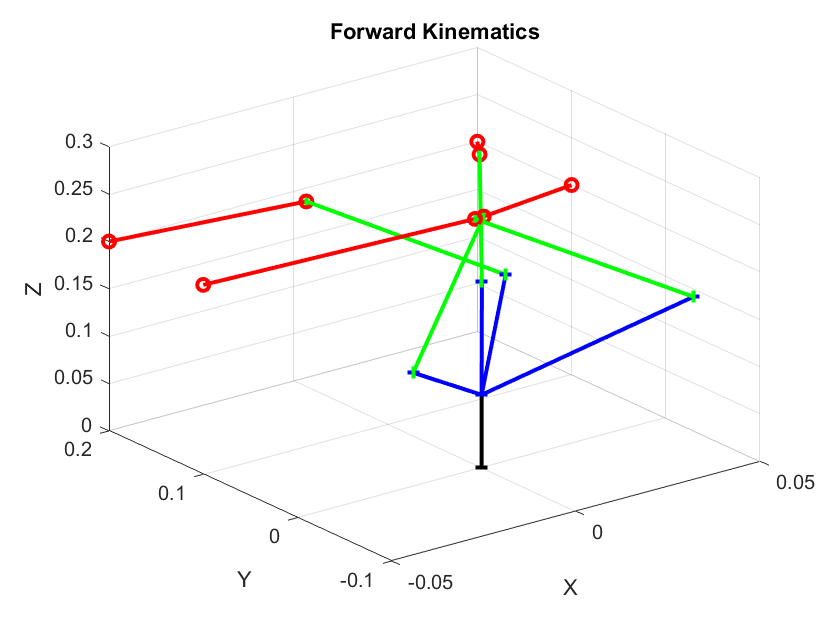

hold off


% Draw a square in x-z plane
XZ1 = [0.05, 0.2, 0.1, -0.523]

XZ1 = 1×4
    0.0500    0.2000    0.1000   -0.5230


XZ2 = [0.05, 0.2, 0.2, -0.523]

XZ2 = 1×4
    0.0500    0.2000    0.2000   -0.5230


XZ3 = [-0.05, 0.2, 0.2, -0.523]

XZ3 = 1×4
   -0.0500    0.2000    0.2000   -0.5230


XZ4 = [-0.05, 0.2, 0.1, -0.523]

XZ4 = 1×4
   -0.0500    0.2000    0.1000   -0.5230



T1 = getFirstValidIKSol( OpenManipIK(XZ1(1),XZ1(2),XZ1(3),XZ1(4)) )

T1 = struct with fields:
    joint1_angle: -0.2450
    joint2_angle: -0.3356
    joint3_angle: 0.6863
    joint4_angle: 0.1723


T2 = getFirstValidIKSol( OpenManipIK(XZ2(1),XZ2(2),XZ2(3),XZ2(4)) )

T2 = struct with fields:
    joint1_angle: -0.2450
    joint2_angle: -0.2880
    joint3_angle: -0.1862
    joint4_angle: 0.9972


T3 = getFirstValidIKSol( OpenManipIK(XZ3(1),XZ3(2),XZ3(3),XZ3(4)) )

T3 = struct with fields:
    joint1_angle: 0.2450
    joint2_angle: -0.2880
    joint3_angle: -0.1862
    joint4_angle: 0.9972


T4 = getFirstValidIKSol( OpenManipIK(XZ4(1),XZ4(2),XZ4(3),XZ4(4)) )

T4 = struct with fields:
    joint1_angle: 0.2450
    joint2_angle: -0.3356
    joint3_angle: 0.6863
    joint4_angle: 0.1723



theta1 = [T1.joint1_angle,T2.joint1_angle,T3.joint1_angle,T4.joint1_angle]

theta1 = 1×4
   -0.2450   -0.2450    0.2450    0.2450


theta2 = [T1.joint2_angle,T2.joint2_angle,T3.joint2_angle,T4.joint2_angle]

theta2 = 1×4
   -0.3356   -0.2880   -0.2880   -0.3356


theta3 = [T1.joint3_angle,T2.joint3_angle,T3.joint3_angle,T4.joint3_angle]

theta3 = 1×4
    0.6863   -0.1862   -0.1862    0.6863


theta4 = [T1.joint4_angle,T2.joint4_angle,T3.joint4_angle,T4.joint4_angle]

theta4 = 1×4
    0.1723    0.9972    0.9972    0.1723



for i = 1:length(theta1)
    [X,Y,Z] = getCoordinate(theta1(i),theta2(i),theta3(i),theta4(i))
    plot3([0,X(1)],[0,Y(1)],[0,Z(1)],'Color','black','LineWidth',2,'Marker','_')
    hold on
    xlabel('X')
    ylabel('Y')
    zlabel('Z')
    title("Forward Kinematics")
    grid on
    plot3([X(1),X(2)],[Y(1),Y(2)],[Z(1),Z(2)],'Color','b','LineWidth',2,'Marker','_')
    plot3([X(2),X(3)],[Y(2),Y(3)],[Z(2),Z(3)],'Color','g','LineWidth',2,'Marker','|')
    plot3([X(3),X(4)],[Y(3),Y(4)],[Z(3),Z(4)],'Color','r','LineWidth',2,'Marker','o')
end

joint1_angle = -0.2450

joint2_angle = -0.3356

joint3_angle = 0.6863

joint4_angle = 0.1723

x1 = 0

y1 = 0

z1 = 0.0770

A = 1×3
         0         0    0.0770


x2 = -0.0047

y2 = -0.0189

z2 = 0.2055

B = 1×3
   -0.0047   -0.0189    0.2055


x3 = 0.0235

y3 = 0.0941

z3 = 0.1629

C = 1×3
    0.0235    0.0941    0.1629


x4 = 0.0500

y4 = 0.2000

z4 = 0.1000

D = 1×3
    0.0500    0.2000    0.1000


X = 1×4
         0   -0.0047    0.0235    0.0500


Y = 1×4
         0   -0.0189    0.0941    0.2000


Z = 1×4
    0.0770    0.2055    0.1629    0.1000


X = 1×4
         0   -0.0047    0.0235    0.0500


Y = 1×4
         0   -0.0189    0.0941    0.2000


Z = 1×4
    0.0770    0.2055    0.1629    0.1000


joint1_angle = -0.2450

joint2_angle = -0.2880

joint3_angle = -0.1862

joint4_angle = 0.9972

x1 = 0

y1 = 0

z1 = 0.0770

A = 1×3
         0         0    0.0770


x2 = -0.0032

y2 = -0.0129

z2 = 0.2063

B = 1×3
   -0.0032   -0.0129    0.2063


x3 = 0.0235

y3 = 0.0941

z3 = 0.2629

C = 1×3
    0.0235    0.0941    0.2629


x4 = 0.0500

y4 = 0.2000

z4 = 0.2000

D = 1×3
    0.0500    0.2000    0.2000


X = 1×4
         0   -0.0032    0.0235    0.0500


Y = 1×4
         0   -0.0129    0.0941    0.2000


Z = 1×4
    0.0770    0.2063    0.2629    0.2000


X = 1×4
         0   -0.0032    0.0235    0.0500


Y = 1×4
         0   -0.0129    0.0941    0.2000


Z = 1×4
    0.0770    0.2063    0.2629    0.2000


joint1_angle = 0.2450

joint2_angle = -0.2880

joint3_angle = -0.1862

joint4_angle = 0.9972

x1 = 0

y1 = 0

z1 = 0.0770

A = 1×3
         0         0    0.0770


x2 = 0.0032

y2 = -0.0129

z2 = 0.2063

B = 1×3
    0.0032   -0.0129    0.2063


x3 = -0.0235

y3 = 0.0941

z3 = 0.2629

C = 1×3
   -0.0235    0.0941    0.2629


x4 = -0.0500

y4 = 0.2000

z4 = 0.2000

D = 1×3
   -0.0500    0.2000    0.2000


X = 1×4
         0    0.0032   -0.0235   -0.0500


Y = 1×4
         0   -0.0129    0.0941    0.2000


Z = 1×4
    0.0770    0.2063    0.2629    0.2000


X = 1×4
         0    0.0032   -0.0235   -0.0500


Y = 1×4
         0   -0.0129    0.0941    0.2000


Z = 1×4
    0.0770    0.2063    0.2629    0.2000


joint1_angle = 0.2450

joint2_angle = -0.3356

joint3_angle = 0.6863

joint4_angle = 0.1723

x1 = 0

y1 = 0

z1 = 0.0770

A = 1×3
         0         0    0.0770


x2 = 0.0047

y2 = -0.0189

z2 = 0.2055

B = 1×3
    0.0047   -0.0189    0.2055


x3 = -0.0235

y3 = 0.0941

z3 = 0.1629

C = 1×3
   -0.0235    0.0941    0.1629


x4 = -0.0500

y4 = 0.2000

z4 = 0.1000

D = 1×3
   -0.0500    0.2000    0.1000


X = 1×4
         0    0.0047   -0.0235   -0.0500


Y = 1×4
         0   -0.0189    0.0941    0.2000


Z = 1×4
    0.0770    0.2055    0.1629    0.1000


X = 1×4
         0    0.0047   -0.0235   -0.0500


Y = 1×4
         0   -0.0189    0.0941    0.2000


Z = 1×4
    0.0770    0.2055    0.1629    0.1000


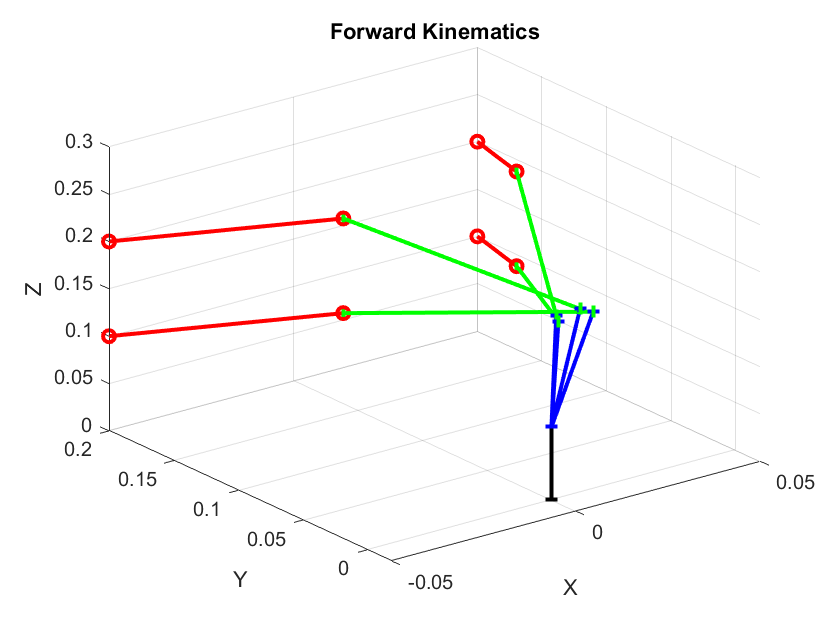

hold off

function [X,Y,Z] = getCoordinate(theta1, theta2, theta3, theta4)
%     joint1_angle = degreeToRadian(theta1)
%     joint2_angle = degreeToRadian(theta2)
%     joint3_angle = degreeToRadian(theta3)
%     joint4_angle = degreeToRadian(theta4)
    
    joint1_angle = theta1
    joint2_angle = theta2
    joint3_angle = theta3
    joint4_angle = theta4
    
    T01 = tfFromDH(0.0, 0.0, 0.0, joint1_angle + pi/2.0);
    T12 = tfFromDH(0.0, 0.0, 0.077, 0.0);
    T23 = tfFromDH(pi/2.0, 0.0, 0.0, -joint2_angle + pi/2.0 - atan(0.024 / 0.128));
    T34 = tfFromDH(0.0, 0.130, 0.0, -joint3_angle - pi/2.0 + atan(0.024 / 0.128));
    T45 = tfFromDH(0.0, 0.124, 0.0, -joint4_angle);
    T56 = tfFromDH(0.0, 0.126, 0.0, 0.0);
    
    link1_position = T01*T12*[0, 0, 0, 1]';
    x1 = link1_position(1)
    y1 = link1_position(2)
    z1 = link1_position(3)
    A = [x1, y1, z1]
    
    link2_position = T01*T12*T23*T34*[0, 0, 0, 1]';
    x2 = link2_position(1)
    y2 = link2_position(2)
    z2 = link2_position(3)
    B = [x2, y2, z2]
    
    link3_position = T01*T12*T23*T34*T45*[0, 0, 0, 1]';
    x3 = link3_position(1)
    y3 = link3_position(2)
    z3 = link3_position(3)
    C = [x3, y3, z3]
    
    tool_position = T01*T12*T23*T34*T45*T56 * [0, 0, 0, 1]';
    x4 = tool_position(1)
    y4 = tool_position(2)
    z4 = tool_position(3)
    D = [x4, y4, z4]
    
    X = [x1 x2 x3 x4]
    Y = [y1 y2 y3 y4]
    Z = [z1 z2 z3 z4]
end


function radian = degreeToRadian(degree)
        radian = degree*pi/180;
end

function tf = tfFromDH(alpha, a, d, theta)
%tfFromDH Converts DH parameters into a homogenous transformation matrix.

    tf = [
        cos(theta), -sin(theta), 0, a;
        sin(theta)*cos(alpha), cos(theta)*cos(alpha), -sin(alpha), -sin(alpha)*d;
        sin(theta)*sin(alpha), cos(theta)*sin(alpha), cos(alpha), cos(alpha)*d;
        0 0 0 1
    ];
end
